# In der Dokumentation verwendete Darstellungen für die Analyse der ausgelegten Traktionsbatterien (Peak-Shaving Auslegung)

## 1.0.) Peak Parameter mit allen Lademethoden

fnStr = fieldnames(BatDimParametersPeakM1);

for n = 1:numel(fnStr)
    
    BatDimParametersPeak.(fnStr{n}).EBat = BatDimParametersPeakM1.(fnStr{n}).EBat;
    BatDimParametersPeak.(fnStr{n}).EBat(:,3) = BatDimParametersPeakM2.(fnStr{n}).EBat(:,2);
    BatDimParametersPeak.(fnStr{n}).EBat(:,4) = BatDimParametersPeakM3.(fnStr{n}).EBat(:,2);

    BatDimParametersPeak.(fnStr{n}).PBat = BatDimParametersPeakM1.(fnStr{n}).PBat;
    BatDimParametersPeak.(fnStr{n}).PBat(:,3) = BatDimParametersPeakM2.(fnStr{n}).PBat(:,2);
    BatDimParametersPeak.(fnStr{n}).PBat(:,4) = BatDimParametersPeakM3.(fnStr{n}).PBat(:,2);

end


## 1.1.) Batterieleistung Peak-Shaving


% Benötigte Batterieleistungen pro Strecke:
fnStr = fieldnames(BatDimParametersCont);

label = string(CR);

for n = 1:numel(fnStr)
    figure
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,8])
    bar((BatDimParametersPeak.(fnStr{n}).PBat(:,1))/1000)
    set(gca, 'xtick', 1:length(label), 'xticklabel', label)
    ylabel('Batterieleistung [MW]')
    xlabel('Deckungsgrad [%]')
    grid()
    title('Auslegung von Traktionsbatterien mit Peak-Shaving Methode')
    subtitle('Batterieleistungen für die Strecke und Fahrtzeit: ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's');
    
    % speichern der plots
    savename = string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Batterieleistung', savename +'.png');
    exportgraphics(gca, filename, 'Resolution',300)
end


## 1.2.) Batteriekapazität Peak-Shaving

% Benötigte Batteriekapazitäten pro Strecke:
fnStr = fieldnames(BatDimParametersCont);

label = string(CR);

for n = 1:numel(fnStr)
    figure
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,8])
    bar((BatDimParametersPeak.(fnStr{n}).EBat))
    set(gca, 'xtick', 1:length(label), 'xticklabel', label)
    ylabel('Batteriekapazität [kWh]')
    xlabel('Deckungsgrad [%]')
    grid()
    legend('ohne Laden','Lademethode 1', 'Lademethode 2', 'Lademethode 3', 'location', 'northwest')
    title('Auslegung von Traktionsbatterien mit Peak-Shaving Methode')
    subtitle('Batteriekapazitäten für die Strecke und Fahrtzeit: ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's');
    
    % speichern der plots
    savename = string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Kapazität', savename +'.png');
    exportgraphics(gca, filename, 'Resolution',300)
end


## 1.3.) Multiplot Kapazität und Leistung Peak-Shaving

% Benötigte Batterieleistungen und Kapazität pro Strecke:
fnStr = fieldnames(BatDimParametersCont);

label = string(CR);

for n = 1:numel(fnStr)
    f1 = figure();
    tiledlayout(2,1)
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,12])

    nexttile
    bar((BatDimParametersPeak.(fnStr{n}).PBat(:,1))/1000)
    set(gca, 'xtick', 1:length(label), 'xticklabel', label)
    ylabel('Batterieleistung [MW]')
    grid()
    title('Auslegung von Traktionsbatterien mit Peak-Shaving Methode')
    subtitle('Leistung und Kapazität für Strecke und Fahrtzeit: ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's');
    
    nexttile
    bar((BatDimParametersPeak.(fnStr{n}).EBat))
    set(gca, 'xtick', 1:length(label), 'xticklabel', label)
    ylabel('Batteriekapazität [kWh]')
    xlabel('Deckungsgrad [%]')
    legend('ohne Laden','Lademethode 1', 'Lademethode 2', 'Lademethode 3', 'location', 'northwest')
    grid()

    % speichern der plots
    savename = string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Multiplot_P_E', savename +'.png');
    exportgraphics(f1, filename, 'Resolution',300)
end


## 1.4.) linearer Fit der Kapazität (Peak-Shaving)


fnStr = fieldnames(BatDimParametersPeak);

for n = 1:numel(fnStr)
    b = CR'\BatDimParametersPeak.(fnStr{n}).EBat(:,1);
    b1 = CR'\BatDimParametersPeak.(fnStr{n}).EBat(:,2);
    b2 = CR'\BatDimParametersPeak.(fnStr{n}).EBat(:,3);
    b3 = CR'\BatDimParametersPeak.(fnStr{n}).EBat(:,4);
    
    y = b * CR';
    y1 = b1 * CR';
    y2 = b2 * CR';
    y3 = b3 * CR';

    Rsq = 1 - sum((BatDimParametersPeak.(fnStr{n}).EBat(:,1) - y).^2)/sum(BatDimParametersPeak.(fnStr{n}).EBat(:,1) - mean(BatDimParametersPeak.(fnStr{n}).EBat(:,1)).^2);
    Rsq1 = 1 - sum((BatDimParametersPeak.(fnStr{n}).EBat(:,2) - y1).^2)/sum(BatDimParametersPeak.(fnStr{n}).EBat(:,2) - mean(BatDimParametersPeak.(fnStr{n}).EBat(:,2)).^2);
    Rsq2 = 1 - sum((BatDimParametersPeak.(fnStr{n}).EBat(:,3) - y2).^2)/sum(BatDimParametersPeak.(fnStr{n}).EBat(:,3) - mean(BatDimParametersPeak.(fnStr{n}).EBat(:,3)).^2);
    Rsq3 = 1 - sum((BatDimParametersPeak.(fnStr{n}).EBat(:,4) - y3).^2)/sum(BatDimParametersPeak.(fnStr{n}).EBat(:,4) - mean(BatDimParametersPeak.(fnStr{n}).EBat(:,4)).^2);
    
    figure
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
    hold on
    % ohne Laden
    plot(CR', BatDimParametersPeak.(fnStr{n}).EBat(:,1),'ob')
    plot(CR',y, 'color', 'b')

    % Lademethode 1
    plot(CR', BatDimParametersPeak.(fnStr{n}).EBat(:,2),'*c')
    plot(CR',y1, 'color', 'c')

    % Lademethode 2
    plot(CR', BatDimParametersPeak.(fnStr{n}).EBat(:,3),'*r')
    plot(CR',y2, 'color', 'r')    

    % Lademethode 3
    plot(CR', BatDimParametersPeak.(fnStr{n}).EBat(:,4),'+g')
    plot(CR',y3, 'color', 'g')  

    grid()
    legend('Kap. ohne Laden [kWh]', 'Lin. Fit: R^2 = ' + string(Rsq), 'Kap. Lademethode 1 [kWh]', 'Lin. Fit Lademethode 1: R^2 = ' + string(Rsq1), 'Kap. Lademethode 2 [kWh]', 'Lin. Fit Lademethode 2: R^2 = ' + string(Rsq2), 'Kap. Lademethode 3 [kWh]', 'Lin. Fit Lademethode 3: R^2 = ' + string(Rsq3), 'location', 'southeast', 'FontSize', 6)
    ylabel('Batteriekapazität [kWh]')
    xlabel('Deckungsgrad [%]')
    title('Linearer Fit für die ausgelegten Batteriekapazitäten')
    subtitle('Strecke und Fahrtzeit: ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's');
    hold off
    
    % speichern der plots
    savename = string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Linearer_Fit', savename +'.png');
    exportgraphics(gca, filename, 'Resolution',300)
end


## 1.4.1.) Nicht-lineares Verhalten der Batterieleistung (Peak-Shaving)

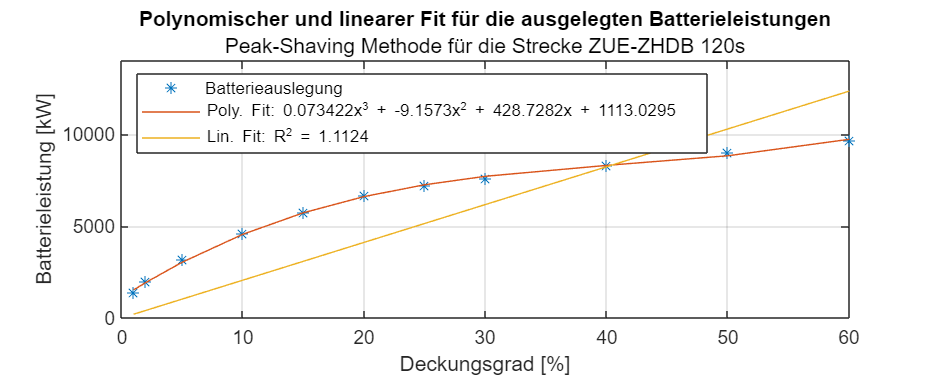

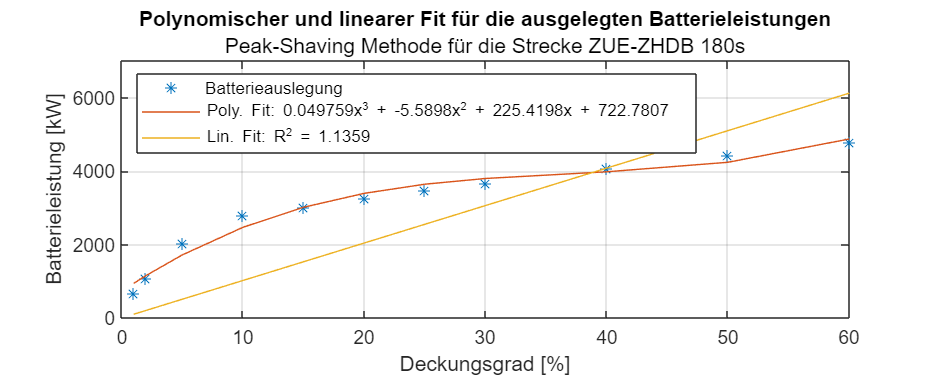

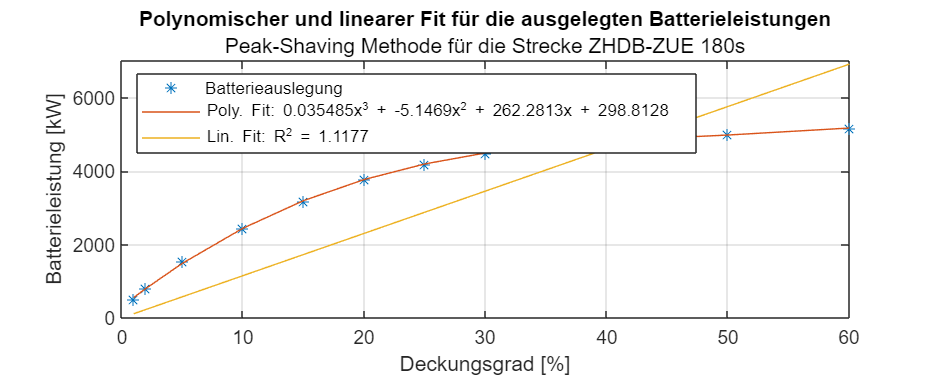

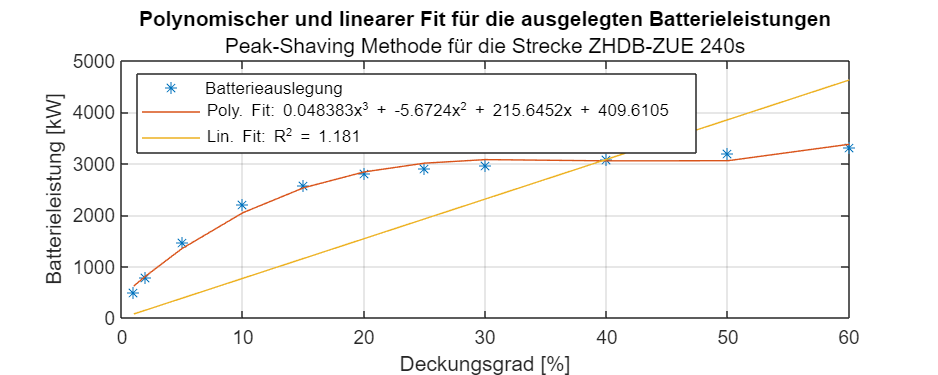

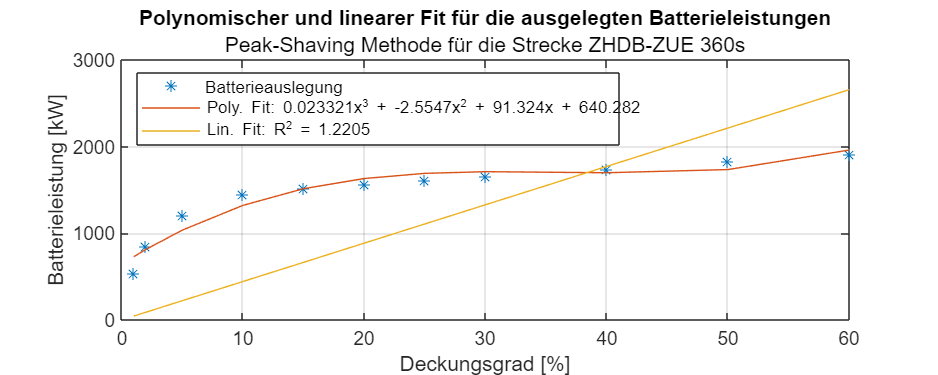

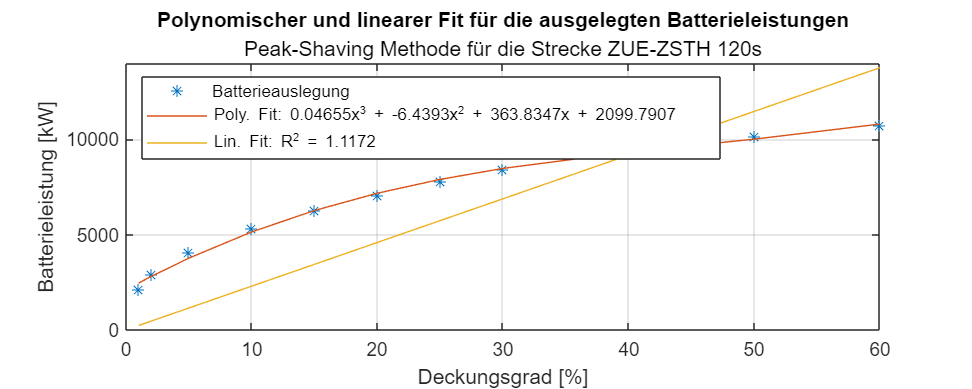

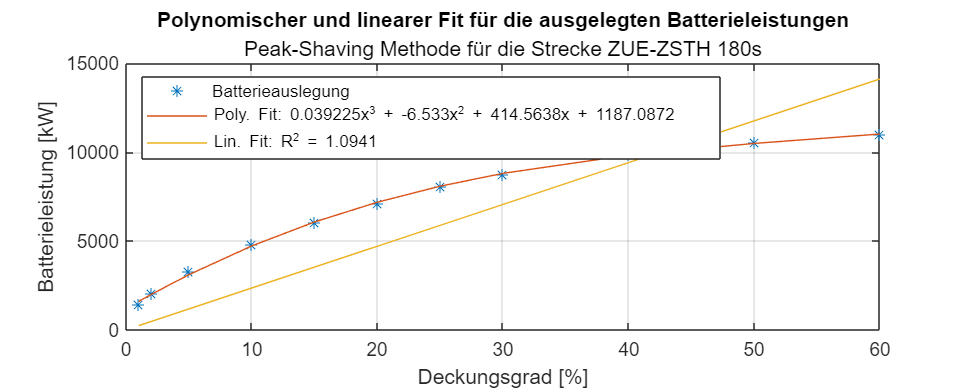

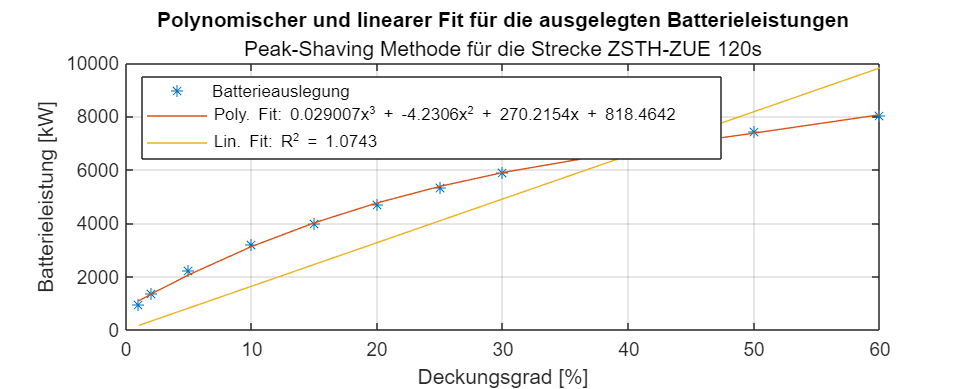


fnStr = fieldnames(BatDimParametersPeak);

for n = 1:numel(fnStr)
    % polynomischer Fit:
    p = polyfit(CR, BatDimParametersPeak.(fnStr{n}).PBat(:,1), 3);
    y1 = polyval(p,CR);

    % linearer Fit:
    b = CR'\BatDimParametersPeak.(fnStr{n}).PBat(:,1);
    y = b * CR';
    Rsq = 1 - sum((BatDimParametersPeak.(fnStr{n}).PBat(:,1) - y).^2)/sum(BatDimParametersPeak.(fnStr{n}).PBat(:,1) - mean(BatDimParametersPeak.(fnStr{n}).PBat(:,1)).^2);
    

    figure
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,8])
    plot(CR, BatDimParametersPeak.(fnStr{n}).PBat(:,1),'*')
    hold on
    plot(CR,y1)
    plot(CR,y)

    legend('Batterieauslegung', 'Poly. Fit: ' + string(p(1)) + 'x^3 + ' + string(p(2)) + 'x^2 + ' + string(p(3)) + 'x + ' + string(p(4)), 'Lin. Fit: R^2 = ' + string(Rsq), 'Location' , 'northwest')
    grid()
    ylabel('Batterieleistung [kW]')
    xlabel('Deckungsgrad [%]')
    title('Polynomischer und linearer Fit für die ausgelegten Batterieleistungen')
    subtitle('Peak-Shaving Methode für die Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's');
    hold off
    
    % speichern der plots
    savename = string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Polynomischer_und_linearer_Fit', savename +'.png');
    exportgraphics(gca, filename, 'Resolution',300)
end

## 4.5.) Verlauf der neuen Leistung und Batterieladestand mit Peak-Shaving Ansatz für jeden Deckungsgrad jeder Fahrt:

fnStr = fieldnames(BatDimPeakM1);
% Achtung, die Ausführung dieser Funktion kann bei vielen Deckungsgraden
% sehr lange dauern!

for n = 1:numel(fnStr)
    
    for k = 1:length(CR)
        CRPname = "PNeu" + string(CR(k)) + "Prozent";
        CRPnameRech = "PNeu" + string(CR(k)) + "ProzentRech";
        CREname = "EBat" + string(CR(k)) + "Prozent";
        CREnameRech = "EBat" + string(CR(k)) + "ProzentRech";

        for i = 1:4

            if(i == 1) % ohne Laden
                figure
                set(gcf, 'units', 'centimeters', 'position', [0,0,20,8])
                hold on
                yyaxis left
                plot(BatDimPeakM1.(fnStr{n}).time, BatDimPeakM1.(fnStr{n}).Leistung/1000)
                plot(BatDimPeakM1.(fnStr{n}).time, BatDimPeakM1.(fnStr{n}).(CRPname)/1000)
                ylabel('Leistung [MW]')
                yyaxis right
                plot(BatDimPeakM1.(fnStr{n}).time, BatDimPeakM1.(fnStr{n}).(CREname))
                title('Batterieeinsatz mit Peak-Shaving Ansatz ohne Laden auf der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')
                subtitle('Leistung und Kapazität mit Deckungsgrad: ' + string(CR(k)) + '%')
                legend('Sim. Leistung', 'Leistung mit Batterie (PBat = ' + string(round(BatDimParametersPeak.(fnStr{n}).PBat(k,i))) + ' kW)', 'Batterieladestand (EBat = ' + string(round(BatDimParametersPeak.(fnStr{n}).EBat(k,i),2)) + ' kWh)', 'FontSize', 7)
                xlabel('Fahrtzeit')
                ylabel('Kapazität [kWh]')
                grid()
                hold off
                % speichern der plots
                savename = 'Peak_ohne_Laden_CR_' + string(CR(k)) +'Prozent_' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
                filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Verlauf_Leistung_Kapazität_ohne_Laden', savename +'.png');
                exportgraphics(gca, filename, 'Resolution',300)

            elseif(i == 2) % Lademethode 1
                figure
                set(gcf, 'units', 'centimeters', 'position', [0,0,20,8])
                hold on
                yyaxis left
                plot(BatDimPeakM1.(fnStr{n}).time, BatDimPeakM1.(fnStr{n}).Leistung/1000)
                plot(BatDimPeakM1.(fnStr{n}).time, BatDimPeakM1.(fnStr{n}).(CRPnameRech)/1000)
                ylabel('Leistung [MW]')
                yyaxis right
                plot(BatDimPeakM1.(fnStr{n}).time, BatDimPeakM1.(fnStr{n}).(CREnameRech))
                title('Batterieeinsatz mit Peak-Shaving Ansatz mit Lademethode 1 auf der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')
                subtitle('Leistung und Kapazität mit Deckungsgrad: ' + string(CR(k)) + '%')
                legend('Sim. Leistung', 'Leistung mit Batterie (PBat = ' + string(round(BatDimParametersPeak.(fnStr{n}).PBat(k,i))) + ' kW)', 'Batterieladestand (EBat = ' + string(round(BatDimParametersPeak.(fnStr{n}).EBat(k,i),2)) + ' kWh)','FontSize', 7)
                xlabel('Fahrtzeit')
                ylabel('Kapazität [kWh]')
                grid()
                hold off
                % speichern der plots
                savename = 'Peak_Lademethode1_CR_' + string(CR(k)) + 'Prozent_' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
                filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Verlauf_Leistung_Kapazität_mit_Lademethode1', savename +'.png');
                exportgraphics(gca, filename, 'Resolution',300)

            elseif(i == 3) % Lademethode 2
                
                figure
                set(gcf, 'units', 'centimeters', 'position', [0,0,20,8])
                hold on
                yyaxis left
                plot(BatDimPeakM2.(fnStr{n}).time, BatDimPeakM2.(fnStr{n}).Leistung/1000)
                plot(BatDimPeakM2.(fnStr{n}).time, BatDimPeakM2.(fnStr{n}).(CRPnameRech)/1000)
                ylabel('Leistung [MW]')
                yyaxis right
                plot(BatDimPeakM2.(fnStr{n}).time, BatDimPeakM2.(fnStr{n}).(CREnameRech))
                title('Batterieeinsatz mit Peak-Shaving Ansatz mit Lademethode 2 auf der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')
                subtitle('Leistung und Kapazität mit Deckungsgrad: ' + string(CR(k)) + '%')
                legend('Sim. Leistung', 'Leistung mit Batterie (PBat = ' + string(round(BatDimParametersPeak.(fnStr{n}).PBat(k,i))) + ' kW)', 'Batterieladestand (EBat = ' + string(round(BatDimParametersPeak.(fnStr{n}).EBat(k,i),2)) + ' kWh)', 'FontSize', 7)
                xlabel('Fahrtzeit')
                ylabel('Kapazität [kWh]')
                grid()
                hold off
                % speichern der plots
                savename = 'Peak_Lademethode2_CR_' + string(CR(k)) + 'Prozent_' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
                filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Verlauf_Leistung_Kapazität_mit_Lademethode2', savename +'.png');
                exportgraphics(gca, filename, 'Resolution',300)

            elseif(i == 4) % Lademethode 3
                figure
                set(gcf, 'units', 'centimeters', 'position', [0,0,20,8])
                hold on
                yyaxis left
                plot(BatDimPeakM3.(fnStr{n}).time, BatDimPeakM3.(fnStr{n}).Leistung/1000)
                plot(BatDimPeakM3.(fnStr{n}).time, BatDimPeakM3.(fnStr{n}).(CRPnameRech)/1000)
                ylabel('Leistung [MW]')
                yyaxis right
                plot(BatDimPeakM3.(fnStr{n}).time, BatDimPeakM3.(fnStr{n}).(CREnameRech))
                title('Batterieeinsatz mit Peak-Shaving Ansatz mit Lademethode 3 auf der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')
                subtitle('Leistung und Kapazität mit Deckungsgrad: ' + string(CR(k)) + '%')
                legend('Sim. Leistung', 'Leistung mit Batterie (PBat = ' + string(round(BatDimParametersPeak.(fnStr{n}).PBat(k,i))) + ' kW)', 'Batterieladestand (EBat = ' + string(round(BatDimParametersPeak.(fnStr{n}).EBat(k,i),2)) + ' kWh)', 'FontSize', 7)
                xlabel('Fahrtzeit')
                ylabel('Kapazität [kWh]')
                grid()
                hold off
                % speichern der plots
                savename = 'Peak_Lademethode3_CR_' + string(CR(k)) + 'Prozent_' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
                filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Verlauf_Leistung_Kapazität_mit_Lademethode3', savename +'.png');
                exportgraphics(gca, filename, 'Resolution',300)

            end
        
        end
    end

end

## 4.6.) Verlauf der neuen Leistung und Batterieladestand mit Peak-Shaving Ansatz für ausgewählte Deckungsgrad

% Deckungsgrade die dargestellt werden sollen:
CRplot = 10;
posCR1 = find(CR == CRplot(1));
% Angabe der Strecke:
fnStr = fieldnames(BatDimPeakM1);
n = 6;
fnStr(n);

f1 = figure();
t = tiledlayout(2,2);
%t.TileSpacing = 'compact';
%t.Padding = 'compact';
set(gcf, 'units', 'centimeters', 'position', [0,0,20,14])

nexttile
hold on
yyaxis left
plot(BatDimPeakM1.(fnStr{n}).time, BatDimPeakM1.(fnStr{n}).Leistung/1000)
plot(BatDimPeakM1.(fnStr{n}).time, BatDimPeakM1.(fnStr{n}).("PNeu" + string(CRplot(1)) + "Prozent")/1000)
ylabel('Leistung [MW]')
xlabel('Fahrtzeit')
yyaxis right
plot(BatDimPeakM1.(fnStr{n}).time, BatDimPeakM1.(fnStr{n}).("EBat" + string(CRplot(1)) + "Prozent"))
ylabel('Energie [kWh]')
title('Ohne Laden und CR: ' + string(CRplot(1)) + '%')
legend('Sim. Leistung', 'P mit Bat (' + string(round(BatDimParametersPeak.(fnStr{n}).PBat(posCR1,1))) + ' kW)', 'EBat (' + string(round(BatDimParametersPeak.(fnStr{n}).EBat(posCR1,1),2)) + ' kWh)','location', 'southwest', 'FontSize', 6)             
grid()
hold off

nexttile
hold on
yyaxis left
plot(BatDimPeakM1.(fnStr{n}).time, BatDimPeakM1.(fnStr{n}).Leistung/1000)
plot(BatDimPeakM1.(fnStr{n}).time, BatDimPeakM1.(fnStr{n}).("PNeu" + string(CRplot(1)) + "ProzentRech")/1000)
ylabel('Leistung [MW]')
xlabel('Fahrtzeit')
yyaxis right
plot(BatDimPeakM1.(fnStr{n}).time, BatDimPeakM1.(fnStr{n}).("EBat" + string(CRplot(1)) + "ProzentRech"))
ylabel('Energie [kWh]')
title('Lademethode 1 und CR: ' + string(CRplot(1)) + '%')
legend('Sim. Leistung', 'P mit Bat (' + string(round(BatDimParametersPeak.(fnStr{n}).PBat(posCR1,2))) + ' kW)', 'EBat (' + string(round(BatDimParametersPeak.(fnStr{n}).EBat(posCR1,2),2)) + ' kWh)','location', 'southwest', 'FontSize', 6)  
grid()
hold off

nexttile
hold on
yyaxis left
plot(BatDimPeakM2.(fnStr{n}).time, BatDimPeakM2.(fnStr{n}).Leistung/1000)
plot(BatDimPeakM2.(fnStr{n}).time, BatDimPeakM2.(fnStr{n}).("PNeu" + string(CRplot(1)) + "ProzentRech")/1000)
ylabel('Leistung [MW]')
xlabel('Fahrtzeit')
yyaxis right
plot(BatDimPeakM2.(fnStr{n}).time, BatDimPeakM2.(fnStr{n}).("EBat" + string(CRplot(1)) + "ProzentRech"))
ylabel('Energie [kWh]')
title('Lademethode 2 und CR: ' + string(CRplot(1)) + '%')
legend('Sim. Leistung', 'P mit Bat (' + string(round(BatDimParametersPeak.(fnStr{n}).PBat(posCR1,3))) + ' kW)', 'EBat (' + string(round(BatDimParametersPeak.(fnStr{n}).EBat(posCR1,3),2)) + ' kWh)','location', 'southwest', 'FontSize', 6)  
grid()
hold off

nexttile
hold on
yyaxis left
plot(BatDimPeakM3.(fnStr{n}).time, BatDimPeakM3.(fnStr{n}).Leistung/1000)
plot(BatDimPeakM3.(fnStr{n}).time, BatDimPeakM3.(fnStr{n}).("PNeu" + string(CRplot(1)) + "ProzentRech")/1000)
ylabel('Leistung [MW]')
xlabel('Fahrtzeit')
yyaxis right
plot(BatDimPeakM3.(fnStr{n}).time, BatDimPeakM3.(fnStr{n}).("EBat" + string(CRplot(1)) + "ProzentRech"))
ylabel('Energie [kWh]')
title('Lademethode 3 und CR: ' + string(CRplot(1)) + '%')
legend('Sim. Leistung', 'P mit Bat (' + string(round(BatDimParametersPeak.(fnStr{n}).PBat(posCR1,4))) + ' kW)', 'EBat (' + string(round(BatDimParametersPeak.(fnStr{n}).EBat(posCR1,4),2)) + ' kWh)','location', 'southwest', 'FontSize', 6)  
grid()
hold off

title(t, 'Vergleich der neuen Leistungsverläufe mit und ohne Laden auf der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')

% speichern der plots
savename = 'Leistungsverläufe_mit_und_ohne_Laden_der_Batterie_' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Vergleich_Leistung_Kapazität_mit_und_ohne_Laden', savename +'.png');
exportgraphics(f1, filename, 'Resolution',300)




## 4.7.) Verlauf der neuen Leistung und Batterieladestand mit Peak-Shaving Ansatz für alle Deckungsgrade

% Angabe der Strecke:
fnStr = fieldnames(BatDimPeakM1);


for n = 1:numel(fnStr)

    for k = 1:length(CR)
        f1 = figure();
        t = tiledlayout(2,2);
        %t.TileSpacing = 'compact';
        %t.Padding = 'compact';
        set(gcf, 'units', 'centimeters', 'position', [0,0,20,14])

        nexttile
        hold on
        yyaxis left
        plot(BatDimPeakM1.(fnStr{n}).time, BatDimPeakM1.(fnStr{n}).Leistung/1000)
        plot(BatDimPeakM1.(fnStr{n}).time, BatDimPeakM1.(fnStr{n}).("PNeu" + string(CR(k)) + "Prozent")/1000)
        ylabel('Leistung [MW]')
        xlabel('Fahrtzeit')
        yyaxis right
        plot(BatDimPeakM1.(fnStr{n}).time, BatDimPeakM1.(fnStr{n}).("EBat" + string(CR(k)) + "Prozent"))
        ylabel('Energie [kWh]')
        title('Ohne Laden und CR: ' + string(CR(k)) + '%')
        legend('Sim. Leistung', 'P mit Bat (' + string(round(BatDimParametersPeak.(fnStr{n}).PBat(k,1))) + ' kW)', 'EBat (' + string(round(BatDimParametersPeak.(fnStr{n}).EBat(k,1),2)) + ' kWh)','location', 'southwest', 'FontSize', 6)
        grid()
        hold off

        nexttile
        hold on
        yyaxis left
        plot(BatDimPeakM1.(fnStr{n}).time, BatDimPeakM1.(fnStr{n}).Leistung/1000)
        plot(BatDimPeakM1.(fnStr{n}).time, BatDimPeakM1.(fnStr{n}).("PNeu" + string(CR(k)) + "ProzentRech")/1000)
        ylabel('Leistung [MW]')
        xlabel('Fahrtzeit')
        yyaxis right
        plot(BatDimPeakM1.(fnStr{n}).time, BatDimPeakM1.(fnStr{n}).("EBat" + string(CR(k)) + "ProzentRech"))
        ylabel('Energie [kWh]')
        title('Lademethode 1 und CR: ' + string(CR(k)) + '%')
        legend('Sim. Leistung', 'P mit Bat (' + string(round(BatDimParametersPeak.(fnStr{n}).PBat(k,2))) + ' kW)', 'EBat (' + string(round(BatDimParametersPeak.(fnStr{n}).EBat(k,2),2)) + ' kWh)','location', 'southwest', 'FontSize', 6)
        grid()
        hold off

        nexttile
        hold on
        yyaxis left
        plot(BatDimPeakM2.(fnStr{n}).time, BatDimPeakM2.(fnStr{n}).Leistung/1000)
        plot(BatDimPeakM2.(fnStr{n}).time, BatDimPeakM2.(fnStr{n}).("PNeu" + string(CR(k)) + "ProzentRech")/1000)
        ylabel('Leistung [MW]')
        xlabel('Fahrtzeit')
        yyaxis right
        plot(BatDimPeakM2.(fnStr{n}).time, BatDimPeakM2.(fnStr{n}).("EBat" + string(CR(k)) + "ProzentRech"))
        ylabel('Energie [kWh]')
        title('Lademethode 2 und CR: ' + string(CR(k)) + '%')
        legend('Sim. Leistung', 'P mit Bat (' + string(round(BatDimParametersPeak.(fnStr{n}).PBat(k,3))) + ' kW)', 'EBat (' + string(round(BatDimParametersPeak.(fnStr{n}).EBat(k,3),2)) + ' kWh)','location', 'southwest', 'FontSize', 6)
        grid()
        hold off

        nexttile
        hold on
        yyaxis left
        plot(BatDimPeakM3.(fnStr{n}).time, BatDimPeakM3.(fnStr{n}).Leistung/1000)
        plot(BatDimPeakM3.(fnStr{n}).time, BatDimPeakM3.(fnStr{n}).("PNeu" + string(CR(k)) + "ProzentRech")/1000)
        ylabel('Leistung [MW]')
        xlabel('Fahrtzeit')
        yyaxis right
        plot(BatDimPeakM3.(fnStr{n}).time, BatDimPeakM3.(fnStr{n}).("EBat" + string(CR(k)) + "ProzentRech"))
        ylabel('Energie [kWh]')
        title('Lademethode 3 und CR: ' + string(CR(k)) + '%')
        legend('Sim. Leistung', 'P mit Bat (' + string(round(BatDimParametersPeak.(fnStr{n}).PBat(k,4))) + ' kW)', 'EBat (' + string(round(BatDimParametersPeak.(fnStr{n}).EBat(k,4),2)) + ' kWh)','location', 'southwest', 'FontSize', 6)
        grid()
        hold off

        title(t, 'Vergleich der neuen Leistungsverläufe mit und ohne Laden auf der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')

        % speichern der plots
        savename = 'CR_'+string(CR(k)) + 'Prozent_Leistungsverläufe_mit_und_ohne_Laden_der_Batterie_' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + '_' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's';
        filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Vergleich_Leistung_Kapazität_mit_und_ohne_Laden', savename +'.png');
        exportgraphics(f1, filename, 'Resolution',300)
    end
end


## 4.9.) Maximale Batterieparameter für jede der vier Strecken (Peak-Shaving)

label = string(CR);

f1 = figure();

set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar(BDPeak.EBatOhneLaden')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Batteriekapazität [kWh]')
legend('ZUE-ZHDB', 'ZHDB-ZUE', 'ZUE-ZSTH', 'ZSTH-ZUE', 'location', 'northwest')
title('Benötigte maximale Batteriekapazitäten jeder Strecke')
subtitle('Auslegung mit Peak-Shaving Methode ohne Laden')
grid()
% speichern der plots
savename = "Max_Batteriekapazitäten_ohne_Laden";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Max_Batterieparameter_aller_Strecken', savename +'.png');
exportgraphics(f1, filename, 'Resolution',300)

f1 = figure();
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar(BDPeak.EBatLademethode1')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Batteriekapazität [kWh]')
legend('ZUE-ZHDB', 'ZHDB-ZUE', 'ZUE-ZSTH', 'ZSTH-ZUE', 'location', 'northwest')
title('Benötigte maximale Batteriekapazitäten jeder Strecke')
subtitle('Auslegung mit Peak-Shaving Methode und Lademethode 1')
grid()
% speichern der plots
savename = "Max_Batteriekapazitäten_mit_Lademethode_1";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Max_Batterieparameter_aller_Strecken', savename +'.png');
exportgraphics(f1, filename, 'Resolution',300)

f1 = figure();
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar(BDPeak.EBatLademethode2')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Batteriekapazität [kWh]')
legend('ZUE-ZHDB', 'ZHDB-ZUE', 'ZUE-ZSTH', 'ZSTH-ZUE', 'location', 'northwest')
title('Benötigte maximale Batteriekapazitäten jeder Strecke')
subtitle('Auslegung mit Peak-Shaving Methode und Lademethode 2')
grid()
% speichern der plots
savename = "Max_Batteriekapazitäten_mit_Lademethode_2";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Max_Batterieparameter_aller_Strecken', savename +'.png');
exportgraphics(f1, filename, 'Resolution',300)

f1 = figure();
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar(BDPeak.EBatLademethode3')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Batteriekapazität [kWh]')
legend('ZUE-ZHDB', 'ZHDB-ZUE', 'ZUE-ZSTH', 'ZSTH-ZUE', 'location', 'northwest')
title('Benötigte maximale Batteriekapazitäten jeder Strecke')
subtitle('Auslegung mit Peak-Shaving Methode und Lademethode 3')
grid()
% speichern der plots
savename = "Max_Batteriekapazitäten_mit_Lademethode_3";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Max_Batterieparameter_aller_Strecken', savename +'.png');
exportgraphics(f1, filename, 'Resolution',300)

f1 = figure();
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar(BDPeak.PBatOhneLaden')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Batterieleistung [kW]')
legend('ZUE-ZHDB', 'ZHDB-ZUE', 'ZUE-ZSTH', 'ZSTH-ZUE', 'location', 'northwest')
title('Benötigte maximale Batterieleistungen jeder Strecke')
subtitle('Auslegung mit Peak-Shaving Methode')
grid()
% speichern der plots
savename = "Max_Batterieleistungen";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Max_Batterieparameter_aller_Strecken', savename +'.png');
exportgraphics(f1, filename, 'Resolution',300)


## 4.9.1) Multiplots Maximale Batterieparameter für jede der vier Strecken

label = string(CR);

f1 = figure();
t = tiledlayout(2,2);
set(gcf, 'units', 'centimeters', 'position', [0,0,20,14])

nexttile
bar(BDPeak.EBatOhneLaden')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Batteriekapazität [kWh]')
legend('ZUE-ZHDB', 'ZHDB-ZUE', 'ZUE-ZSTH', 'ZSTH-ZUE', 'location', 'northwest')
%title('Benötigte maximale Batteriekapazitäten jeder Strecke')
subtitle('Ohne Laden')
grid()

nexttile
bar(BDPeak.EBatLademethode1')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Batteriekapazität [kWh]')
legend('ZUE-ZHDB', 'ZHDB-ZUE', 'ZUE-ZSTH', 'ZSTH-ZUE', 'location', 'northwest')
subtitle('Lademethode 1')
grid()

nexttile
bar(BDPeak.EBatLademethode2')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Batteriekapazität [kWh]')
legend('ZUE-ZHDB', 'ZHDB-ZUE', 'ZUE-ZSTH', 'ZSTH-ZUE', 'location', 'northwest')
subtitle('Lademethode 2')
grid()

nexttile
bar(BDPeak.EBatLademethode3')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Batteriekapazität [kWh]')
legend('ZUE-ZHDB', 'ZHDB-ZUE', 'ZUE-ZSTH', 'ZSTH-ZUE', 'location', 'northwest')
subtitle('Lademethode 3')
grid()

title(t, 'Benötigte maximale Batteriekapazitäten für Peak-Shaving mit verschiedenen Lademethoden')

% speichern der plots
savename = "Multiplot_Max_Batteriekapazitäten";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Max_Batterieparameter_aller_Strecken', savename +'.png');
exportgraphics(f1, filename, 'Resolution',300)



## 4.10.) Verlauf der Gesamtleistung mit Batterieeinsatz nach Peak-Shaving Ansatz

time = seconds(0:0.1:86399.9)'; 
time.Format = 'hh:mm:ss.S';
figure
tiledlayout(2,1);
set(gcf, 'units', 'centimeters', 'position', [0,0,20,14])

nexttile
hold on
plot(time, P_totSim/1000)
plot(time, P_totSimBatDimPeakM1(:,5)/1000)
plot(time, P_totSimBatDimPeakM1(:,9)/1000)
xtickformat('hh:mm')
xlabel('Uhrzeit')
ylabel('Leistung [MW]')
title('Vergleich der simulierten mit der neuen Gesamtleistung im Speisepunkt Museumstrasse')
subtitle('Batterieeinsatz ohne Laden der Batterie mit Peak-Shaving Methode')
legend('Sim. Leistung', 'CR: 15%', 'CR: 40%')
grid()
hold off

nexttile
hold on
plot(time(215000:225000), P_totSim(215000:225000)/1000)
plot(time(215000:225000), P_totSimBatDimPeakM1(215000:225000,5)/1000)
plot(time(215000:225000), P_totSimBatDimPeakM1(215000:225000,9)/1000)
%plot(time(285000:295000), P_totSim(285000:295000)/1000)
xtickformat('hh:mm')
%xticks(time(285000):minutes(5):time(295000))
xticks(time(215000):minutes(5):time(225000))
xlabel('Uhrzeit')
ylabel('Leistung [MW]')
grid()
hold off

% speichern der plots
savename = "Vergleich_Gesamtleistung_mit_und_ohne_Peak_Batterieeinsatz_Zoomed";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Gesamtleistung_mit_Peak_Shaving_Batterieeinsatz\', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)


figure
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
hold on
plot(time(215000:225000), P_totSim(215000:225000)/1000)
plot(time(215000:225000), P_totSimBatDimPeakM1(215000:225000,8)/1000)
plot(time(215000:225000), P_totSimBatDimPeakM1(215000:225000,19)/1000)
plot(time(215000:225000), P_totSimBatDimPeakM2(215000:225000,19)/1000)
plot(time(215000:225000), P_totSimBatDimPeakM3(215000:225000,19)/1000)
xtickformat('hh:mm')
xticks(time(215000):minutes(5):time(225000))
xlabel('Uhrzeit')
ylabel('Leistung [MW]')
legend('Sim. Leistung', 'CR: 30% ohne Laden', 'CR: 30% Lademethode 1', 'CR: 30% Lademethode 2', 'CR: 30% Lademethode 3')
title('Vergleich der simulierten mit der neuen Gesamtleistung im Speisepunkt Museumstrasse')
subtitle('Batterieeinsatz mit Laden der Batterie mit Peak-Shaving Methode')
grid()
hold off
% speichern der plots
savename = "Vergleich_Gesamtleistung_mit_Kont_Batterieeinsatz_Zoomed_mit_ohne_Laden";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Gesamtleistung_mit_Peak_Shaving_Batterieeinsatz\', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)



## 4.11.) Vergleich der 8 min Mittelwerte mit den Verläufen der Gesamtleistung (Peak-Shaving)

P_totSimMean = zeros(288,1);

n = 1;
for i = 1:3000:864000
    if (i < 4800)
        P_totSimMean(n,1) = mean(P_totSim(1:i));
    else
        P_totSimMean(n,1) = mean(P_totSim(i-4800:i));
    end
    n = n + 1;
end

P_totSimBatDimPeakMeanM1 = zeros(288,length(CR));
P_totSimBatDimPeakMeanM2 = zeros(288,length(CR));
P_totSimBatDimPeakMeanM3 = zeros(288,length(CR));

for k = 1:length(CR)*2
    n = 1;
    for i = 1:3000:864000
        if (i < 4800)
            P_totSimBatDimPeakMeanM1(n,k) = mean(P_totSimBatDimPeakM1(1:i,k));
            P_totSimBatDimPeakMeanM2(n,k) = mean(P_totSimBatDimPeakM2(1:i,k));
            P_totSimBatDimPeakMeanM3(n,k) = mean(P_totSimBatDimPeakM3(1:i,k));
        else
            P_totSimBatDimPeakMeanM1(n,k) = mean(P_totSimBatDimPeakM1(i-4800:i,k));
            P_totSimBatDimPeakMeanM2(n,k) = mean(P_totSimBatDimPeakM2(i-4800:i,k));
            P_totSimBatDimPeakMeanM3(n,k) = mean(P_totSimBatDimPeakM3(i-4800:i,k));
        end
        n = n + 1;
    end
end


% Erstellung eines Zeitarrays für die 5 min. Mittelwerte (alle 5 Min.)
time2 = seconds(0:300:86400-300);
time2.Format = 'hh:mm:ss.S';

for n = 1:length(CR)
    figure
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,14])
    tiledlayout(2,2)


    nexttile([1 2])
    %nexttile
    hold on
    % Montag:
    plot(time2, Meas.P8minMittelMW(1:length(time2)))
    % Sonntag:
    %plot(time2, Meas.P8minMittelMW(1729:2016))


    plot(time2, P_totSimMean/1000)
    plot(time2, P_totSimBatDimPeakMeanM1(:,n)/1000)
    plot(time2, P_totSimBatDimPeakMeanM1(:,n+length(CR))/1000)
    plot(time2, P_totSimBatDimPeakMeanM2(:,n+length(CR))/1000)
    plot(time2, P_totSimBatDimPeakMeanM3(:,n+length(CR))/1000)
    title('Vergleich der Messwerte mit dem Simulierten Leistungsverlauf mit Batterieeinsatz')
    subtitle('Batterieeinsatz mit Peak-Shaving Ansatz mit und ohne Laden')
    grid()
    legend('Gemessene Leistung', 'Sim. Leistung', 'CR: ' + string(CR(n)) + '% ohne Laden', 'CR: ' + string(CR(n)) + '% mit Lademethode 1' , 'CR: ' + string(CR(n)) + '% mit Lademethode 2' ,'CR: ' + string(CR(n)) + '% mit Lademethode 3','Location', 'northwest', 'FontSize', 6)
    xlabel('Uhrzeit')
    ylabel('Leistung [MW]')
    xtickformat('hh:mm')
    hold off

    nexttile
    hold on
    % Montag:
    plot(time2(70:115), Meas.P8minMittelMW(70:115))
    plot(time2(70:115), P_totSimMean(70:115)/1000)
    % Sonntag:
    %plot(time2(70:115), Meas.P8minMittelMW(70:115))
    plot(time2(70:115), P_totSimBatDimPeakMeanM1(70:115,n)/1000)
    plot(time2(70:115), P_totSimBatDimPeakMeanM1(70:115,n+length(CR))/1000)
    plot(time2(70:115), P_totSimBatDimPeakMeanM2(70:115,n+length(CR))/1000)
    plot(time2(70:115), P_totSimBatDimPeakMeanM3(70:115,n+length(CR))/1000)
    subtitle('06:00 - 09:00 Uhr')
    grid()
    xlabel('Uhrzeit')
    ylabel('Leistung [MW]')
    xtickformat('hh:mm')
    hold off

    nexttile
    hold on
    plot(time2(190:235), Meas.P8minMittelMW((190:235)))
    plot(time2(190:235), P_totSimMean(190:235)/1000)

    plot(time2(190:235), P_totSimBatDimPeakMeanM1(190:235,n)/1000)
    plot(time2(190:235), P_totSimBatDimPeakMeanM1(190:235,n+length(CR))/1000)
    plot(time2(190:235), P_totSimBatDimPeakMeanM2(190:235,n+length(CR))/1000)
    plot(time2(190:235), P_totSimBatDimPeakMeanM3(190:235,n+length(CR))/1000)
    subtitle('16:00 - 19:00 Uhr')
    grid()
    xlabel('Uhrzeit')
    ylabel('Leistung [MW]')
    xtickformat('hh:mm')
    hold off

    % speichern der plots
    savename = "CR_" + string(CR(n)) + "_Vergleich_Messwerte_mit_Batterieeinsatz";
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\MesswertVergleich\', savename +'.png');
    exportgraphics(gcf, filename, 'Resolution',300)
end

## 4.11.) Vergleich der Leistungsspitzen in der Echtzeitsimulation mit kontinuierlicher Methode

label = string(CR);
clearvars LastSpitzenPeak;
for k = 1:length(CR)
    
    LastSpitzenPeak(k,1) = max(P_totSimBatDimPeakM1(:,k));
    LastSpitzenPeak(k,2) = max(P_totSimBatDimPeakM1(:,k+length(CR)));
    LastSpitzenPeak(k,3) = max(P_totSimBatDimPeakM2(:,k+length(CR)));
    LastSpitzenPeak(k,4) = max(P_totSimBatDimPeakM3(:,k+length(CR)));


end

figure()
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar(LastSpitzenPeak/1000)
yline(max(P_totSim)/1000, '-','max. Simulierte Leistungsspitze ohne Batterie','LabelHorizontalAlignment','left')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('max. Leistungsspitze [MW]')
ylim([0,max(P_totSim)/1000+5])
legend('ohne Laden', 'Lademethode 1', 'Lademethode 2','Lademethode 3', 'location', 'northeast')
title('Vergleich der Leistungsspitzen der simulierten Gesamtleistung mit und ohne Traktionsbatterie')
subtitle('Peak-Shaving Methode mit und ohne Lademethoden')
grid()

% speichern der plots
savename = "Vergleich_der_Leistungsspitzen_mit_Peak_Shaving_Ansatz";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Analyse_Leistungsspitzen\', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)

LastSpitzenPeak(:,1) = LastSpitzenPeak(:,1)/1000;
LastSpitzenPeak(:,2) = LastSpitzenPeak(:,2)/1000;
LastSpitzenPeak(:,3) = LastSpitzenPeak(:,3)/1000;
LastSpitzenPeak(:,4) = LastSpitzenPeak(:,4)/1000;
LastSpitzenPeak(:,5) = (1 - LastSpitzenPeak(:,1)/(max(P_totSim)/1000))*100;
LastSpitzenPeak(:,6) = (1 - LastSpitzenPeak(:,2)/(max(P_totSim)/1000))*100;
LastSpitzenPeak(:,7) = (1 - LastSpitzenPeak(:,3)/(max(P_totSim)/1000))*100;
LastSpitzenPeak(:,8) = (1 - LastSpitzenPeak(:,4)/(max(P_totSim)/1000))*100;


## 4.12.) Vergleich der Leistungsspitzen mit den 8 Min. Mittelwerten mit Peak-Shaving Methode

label = string(CR);
clearvars LastSpitzenPeakMean;
for k = 1:length(CR)
    
    LastSpitzenPeakMean(k,1) = max(P_totSimBatDimPeakMeanM1(:,k));
    LastSpitzenPeakMean(k,2) = max(P_totSimBatDimPeakMeanM1(:,k+length(CR)));
    LastSpitzenPeakMean(k,3) = max(P_totSimBatDimPeakMeanM2(:,k+length(CR)));
    LastSpitzenPeakMean(k,4) = max(P_totSimBatDimPeakMeanM3(:,k+length(CR)));

end

figure()
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar(LastSpitzenPeakMean/1000)
yline(max(P_totSimMean)/1000, '-','max. Simulierte Leistungsspitze ohne Batterie', 'LabelHorizontalAlignment','right')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('max. Leistungsspitze [MW]')
ylim([0,max(P_totSimMean)/1000+2])
legend('ohne Laden', 'Lademethode 1', 'Lademethode 2','Lademethode 2', 'location', 'southwest')
title('Vergleich der Leistungsspitzen der 8 Min. Mittelwerte mit und ohne Traktionsbatterie')
subtitle('Peak-Shaving Methode mit und ohne Lademethoden')
grid()

% speichern der plots
savename = "Vergleich_der_Leistungsspitzen_der_8Min_Mittelwerte_mit_Peak_Shaving_Ansatz";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Auslegung_Traktionsbatterie_Peak\Analyse_Leistungsspitzen\', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)


LastSpitzenPeakMean(:,1) = LastSpitzenPeakMean(:,1)/1000;
LastSpitzenPeakMean(:,2) = LastSpitzenPeakMean(:,2)/1000;
LastSpitzenPeakMean(:,3) = LastSpitzenPeakMean(:,3)/1000;
LastSpitzenPeakMean(:,4) = LastSpitzenPeakMean(:,4)/1000;
LastSpitzenPeakMean(:,5) = (1 - LastSpitzenPeakMean(:,1)/(max(P_totSimMean)/1000))*100;
LastSpitzenPeakMean(:,6) = (1 - LastSpitzenPeakMean(:,2)/(max(P_totSimMean)/1000))*100;
LastSpitzenPeakMean(:,7) = (1 - LastSpitzenPeakMean(:,3)/(max(P_totSimMean)/1000))*100;
LastSpitzenPeakMean(:,8) = (1 - LastSpitzenPeakMean(:,4)/(max(P_totSimMean)/1000))*100;


## 5.1. Vergleich der ausgelegten Batterieleistungen mit Kontinuierlicher und Peak-Shaving Methode

label = string(CR);

figure()
set(gcf, 'units', 'centimeters', 'position', [0,0,20,14])
t = tiledlayout(2,2);

nexttile
bar([BDCont.PBatMitLaden(1,:)'/1000, BDPeak.PBatOhneLaden(:,1)/1000])
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Ausgelegte Batterieleistung [MW]')
legend('Kontinuierlich', 'Peak-Shaving','location', 'northwest')
subtitle('ZUE-ZHDB')
grid()

nexttile
bar([BDCont.PBatMitLaden(2,:)'/1000, BDPeak.PBatOhneLaden(:,2)/1000])
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Ausgelegte Batterieleistung [MW]')
legend('Kontinuierlich', 'Peak-Shaving','location', 'northwest')
subtitle('ZHDB-ZUE')
grid()

nexttile
bar([BDCont.PBatMitLaden(3,:)'/1000, BDPeak.PBatOhneLaden(:,3)/1000])
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Ausgelegte Batterieleistung [MW]')
legend('Kontinuierlich', 'Peak-Shaving','location', 'northwest')
subtitle('ZUE-ZSTH')
grid()

nexttile

bar([BDCont.PBatMitLaden(4,:)'/1000, BDPeak.PBatOhneLaden(:,4)/1000])
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('Ausgelegte Batterieleistung [MW]')
legend('Kontinuierlich', 'Peak-Shaving','location', 'northwest')
subtitle('ZUE-ZSTH')
grid()

title(t,'Vergleich der ausgelegten Batterieleistungen mit Kontinuierlicher und Peak-Shaving Methode')
% speichern der plots
savename = "Vergleich_Batterieleistungen_Cont_und_Peak";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Vergleich_Auslegemethode_Cont_und_Peak\', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)


## 5.2. Vergleich der ausgelegten Batteriekapazitäten mit Kontinuierlicher und Peak-Shaving Methode

label = string(CR);

figure()
set(gcf, 'units', 'centimeters', 'position', [0,0,20,18])
t = tiledlayout(4,1);

nexttile
bar([BDCont.EBatOhneLaden(1,:)', BDCont.EBatMitLaden(1,:)', BDPeak.EBatOhneLaden(:,1) , BDPeak.EBatLademethode1(:,1) , BDPeak.EBatLademethode2(:,1) , BDPeak.EBatLademethode3(:,1)])
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
legend('Kont. ohne Laden','Kont. mit Laden', 'Peak ohne Laden', 'Peak Lademethode 1', 'Peak Lademethode 2', 'Peak Lademethode 3','location', 'northwest', 'FontSize', 6)
subtitle('ZUE-ZHDB')
grid()

nexttile
bar([BDCont.EBatOhneLaden(2,:)', BDCont.EBatMitLaden(2,:)', BDPeak.EBatOhneLaden(:,2) , BDPeak.EBatLademethode1(:,2) , BDPeak.EBatLademethode2(:,2) , BDPeak.EBatLademethode3(:,2)])
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
subtitle('ZHDB-ZUE')
grid()

nexttile
bar([BDCont.EBatOhneLaden(3,:)', BDCont.EBatMitLaden(3,:)', BDPeak.EBatOhneLaden(:,3) , BDPeak.EBatLademethode1(:,3) , BDPeak.EBatLademethode2(:,3) , BDPeak.EBatLademethode3(:,3)])

set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
subtitle('ZUE-ZSTH')
grid()

nexttile
bar([BDCont.EBatOhneLaden(4,:)', BDCont.EBatMitLaden(4,:)', BDPeak.EBatOhneLaden(:,4) , BDPeak.EBatLademethode1(:,4) , BDPeak.EBatLademethode2(:,4) , BDPeak.EBatLademethode3(:,4)])
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')

subtitle('ZUE-ZSTH')
grid()

ylabel(t, 'Ausgelegte Batteriekapazität [kWh]')
title(t,'Vergleich der ausgelegten Batteriekapazitäten mit Kontinuierlicher und Peak-Shaving Methode')
% speichern der plots
savename = "Vergleich_Batteriekapazitäten_Cont_und_Peak";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Vergleich_Auslegemethode_Cont_und_Peak\', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)



## 5.3. Vergleich der Reduktion der Leistungsspitzen mit Kontinuierlicher und Peak-Shaving Methode

figure()
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar([LastSpitzenPeak(:,1:4), LastSpitzenCont(:,1:2)])
yline(max(P_totSim)/1000, '-','max. Simulierte Leistungsspitze ohne Batterie','LabelHorizontalAlignment','left')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('max. Leistungsspitze [MW]')
ylim([0,max(P_totSim)/1000+5])
legend('Peak ohne Laden', 'Peak Lademethode 1', 'Peak Lademethode 2','Peak Lademethode 3', 'Cont ohne Laden', 'Cont mit Laden', 'location', 'northeast')
title('Vergleich der Leistungsspitzen der Gesamtleistung mit Batterieeinsatz')
subtitle('Vergleich Kontinuierliche und Peak-Shaving Methode')
grid()


% speichern der plots
savename = "Vergleich_Leistungsspitzen_Cont_und_Peak";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Vergleich_Auslegemethode_Cont_und_Peak\', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)


## 5.4. Vergleich Reduktionsverhältnis Kont. und Peak.

% Verhältnis benötigte Batterieleistungen:

PBatRatio = BDPeak.PBatOhneLaden./(BDCont.PBatOhneLaden');

PReducedRatio(:,1) = LastSpitzenPeak(:,5)./LastSpitzenCont(:,3);
PReducedRatio(:,2) = LastSpitzenPeak(:,6)./LastSpitzenCont(:,3);
PReducedRatio(:,3) = LastSpitzenPeak(:,7)./LastSpitzenCont(:,3);
PReducedRatio(:,4) = LastSpitzenPeak(:,8)./LastSpitzenCont(:,3);


## 5.4. Vergleich Reduktion Leistungsspitzen 8 min Werte Kontinuierlich und Peak

figure()
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar([LastSpitzenPeakMean(:,1:4), LastSpitzenContMean(:,1:2)])
yline(max(P_totSimMean)/1000, '-','max. Simulierte Leistungsspitze ohne Batterie','LabelHorizontalAlignment','left')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
xlabel('Deckungsgrad [%]')
ylabel('max. Leistungsspitze [MW]')
ylim([0,max(P_totSimMean)/1000+2])
legend('Peak ohne Laden', 'Peak Lademethode 1', 'Peak Lademethode 2','Peak Lademethode 3', 'Cont ohne Laden', 'Cont mit Laden', 'location', 'northeast')
title('Vergleich der Leistungsspitzen der 8 Min. Mittelwerte mit Batterieeinsatz')
subtitle('Vergleich Kontinuierliche und Peak-Shaving Methode')
grid()


% speichern der plots
savename = "Vergleich_Leistungsspitzen_Cont_und_Peak_8Min_Mittelwerte";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Vergleich_Auslegemethode_Cont_und_Peak\', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)

